# **Circuitos Electricos II**

**Roberto Sanchez Figueroa**

**brrsanchezfi@unal.edu.co**

***Monitoria Circuitos II***

***GIT-HUB:  ***[***https://github.com/brrsanchezfi/Circuitos_2022_1***](https://github.com/brrsanchezfi/Circuitos_2022_1)

# **Soluciones propuestas para los ejercicios del taller 2**

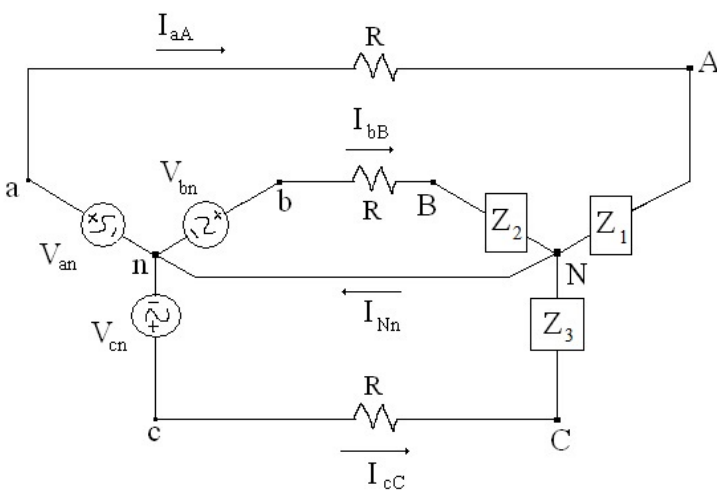

## Analisis en el domio de la frecuencia

*matlab symbolico*

syms I1 I2 I3 V_an V_bn V_cn R Z_1 Z_2 Z_3 %I_aA I_bB I_cC

sys = [V_an - V_bn == I1*(2*R + Z_1 + Z_2) - I2*(R + Z_2);
       V_bn == I2*(R + Z_2) - I1*(R + Z_2); %planteamiento de la matriz de mallas
       -V_cn == I3*(R + Z_3)]

$$sys = \left(\begin{array}{c} V_{\mathrm{an}}-V_{\mathrm{bn}}=I_{1}\,\left(2\,R+Z_{1}+Z_{2}\right)-I_{2}\,\left(R+Z_{2}\right)\\ V_{\mathrm{bn}}=I_{2}\,\left(R+Z_{2}\right)-I_{1}\,\left(R+Z_{2}\right)\\ -V_{\mathrm{cn}}=I_{3}\,\left(R+Z_{3}\right) \end{array}\right)$$


sol = solve(sys,[I1 I2 I3]); %solucion del sistema

I1 = sol.I1;
I2 = sol.I2;
I3 = sol.I3;

I_aA = simplify(I1)   %corrientes de linea apartir de las corrientes de malla

$$I\_aA = \frac{V_{\mathrm{an}}}{R+Z_{1}}$$

I_bB = simplify(I2 - I1)

$$I\_bB = \frac{V_{\mathrm{bn}}}{R+Z_{2}}$$

I_cC = -I3

$$I\_cC = \frac{V_{\mathrm{cn}}}{R+Z_{3}}$$


Z1 = 5 + 5i;  %valores de impedancias y resitencias
Z2 = 5 + 5i;
Z3 = 5 + 5i;
R_n = 0.5;

Van = pol2com(100,0);   % Voltajes, polares a complejos
Vbn = pol2com(100,240);
Vcn = pol2com(100,120);

IaA = double(subs(I_aA,[V_an R Z_1],[Van R_n Z1])) %sustitucion de variables

IaA = 9.9548 - 9.0498i

IbB = double(subs(I_bB,[V_bn R Z_2],[Vbn R_n Z2]))

IbB = -12.8147 - 4.0962i

IcC = double(subs(I_cC,[V_cn R Z_3],[Vcn R_n Z3]))

IcC = 2.8600 + 13.1460i

Potencia compleja


$$S={\textrm{VI}}^* ={\left|I\right|}^2 Z$$


S = (Van*conj(IaA) + Vbn*conj(IbB) + Vcn*conj(IcC))*0.5  % el 0.5 es para corregir el RMS

S = 1.4932e+03 + 1.3575e+03i

Potencia de la carga

S_carga = (abs(IaA)^2*(Z1) +abs(IbB)^2*(Z2) + abs(IcC)^2*(Z3))*0.5

S_carga = 1.3575e+03 + 1.3575e+03i

Potencia de perdidas

S_perdidas = (abs(IaA)^2*(R_n) +abs(IbB)^2*(R_n) + abs(IcC)^2*(R_n))*0.5

S_perdidas = 135.7466

Balance de potencia 

Balance = round(S - (S_carga + S_perdidas))

Balance = 0

## Analisis en el dominio del tiempo

*Voltajes expresador en funcion del tiempo y en RMS*

Van_t = com2pol(Van)     %convierte complejo a polar, VALORES PICO

Van_t =    100     0


Vbn_t = com2pol(Vbn)

Vbn_t =   100.0000 -120.0000


Vcn_t = com2pol(Vcn)

Vcn_t =   100.0000  120.0000


IaA_t = com2pol(IaA)

IaA_t =    13.4535  -42.2737


IbB_t = com2pol(IbB)

IbB_t =    13.4535 -162.2737


IcC_t = com2pol(IcC)

IcC_t =    13.4535   77.7263


clc
syms V_an V_bn V_cn R_L Z_1 Z_2 Z_3 I_aA I_bB I_cC t a1 a2 a3 a4 a5 a6 w

Va= (V_an/sqrt(2))*cosd((w*t) + a1); %funciones en el dominio del tiempo
Vb= (V_bn/sqrt(2))*cosd((w*t) + a2);
Vc= (V_cn/sqrt(2))*cosd((w*t) + a3);
Ia= (I_aA/sqrt(2))*cosd((w*t) + a4);
Ib= (I_bB/sqrt(2))*cosd((w*t) + a5);
Ic= (I_cC/sqrt(2))*cosd((w*t) + a6);


p1 = Va*Ia

$$p1 = \frac{I_{\mathrm{aA}}\,V_{\mathrm{an}}\,\cos\left(\frac{\pi \,\left(a_{1}+t\,w\right)}{180}\right)\,\cos\left(\frac{\pi \,\left(a_{4}+t\,w\right)}{180}\right)}{2}$$

p2 = Vb*Ib

$$p2 = \frac{I_{\mathrm{bB}}\,V_{\mathrm{bn}}\,\cos\left(\frac{\pi \,\left(a_{2}+t\,w\right)}{180}\right)\,\cos\left(\frac{\pi \,\left(a_{5}+t\,w\right)}{180}\right)}{2}$$

p3 = Vc*Ic

$$p3 = \frac{I_{\mathrm{cC}}\,V_{\mathrm{cn}}\,\cos\left(\frac{\pi \,\left(a_{3}+t\,w\right)}{180}\right)\,\cos\left(\frac{\pi \,\left(a_{6}+t\,w\right)}{180}\right)}{2}$$

p1 = subs(p1,[V_an I_aA w a1 a4],[Van_t(1) IaA_t(1) 2*pi*60 Van_t(2) IaA_t(2)])

$$p1 = \frac{10000\,\sqrt{221}\,\cos\left(\frac{\pi \,\left(120\,\pi \,t-\frac{5949492814231875}{140737488355328}\right)}{180}\right)\,\cos\left(\frac{2\,t\,\pi^{2}}{3}\right)}{221}$$

p2 = subs(p2,[V_bn I_bB w a2 a5],[Vbn_t(1) IbB_t(1) 2*pi*60 Vbn_t(2) IbB_t(2)])

$$p2 = \frac{10000\,\sqrt{221}\,\cos\left(\frac{\pi \,\left(120\,\pi \,t-120\right)}{180}\right)\,\cos\left(\frac{\pi \,\left(120\,\pi \,t-\frac{356843615888613}{2199023255552}\right)}{180}\right)}{221}$$

p3 = subs(p3,[V_cn I_cC w a3 a6],[Vcn_t(1) IcC_t(1) 2*pi*60 Vcn_t(2) IcC_t(2)])

$$p3 = \frac{10000\,\sqrt{221}\,\cos\left(\frac{\pi \,\left(120\,\pi \,t+\frac{5469502894203743}{70368744177664}\right)}{180}\right)\,\cos\left(\frac{\pi \,\left(120\,\pi \,t+120\right)}{180}\right)}{221}$$

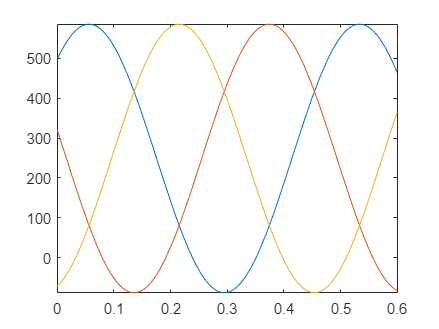

p_total = 2*(p1 +p2 +p3); %el 2 es por el valor RMS (VER GUIA PAG 15)

fplot(p1,[0 0.6])
hold on
fplot(p2,[0 0.6])
fplot(p3,[0 0.6])
hold off

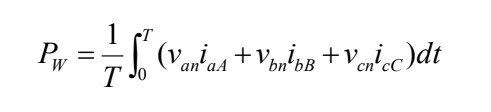

P_total = ((60)*int(p_total,t,0,(1/(60))))

$$P\_total = \frac{10000\,\sqrt{221}\,\left(\cos\left(\frac{2974746407115937\,\pi }{12666373951979520}\right)+\cos\left(\frac{30986941740791\,\pi }{131941395333120}\right)+\cos\left(\frac{132210951427375\,\pi }{562949953421312}\right)\right)}{221}+\frac{10000\,\sqrt{221}\,\left(45\,\sin\left(\frac{1247378243543903\,\pi }{12666373951979520}\right)-45\,\sin\left(\frac{132210951427375\,\pi }{562949953421312}-\frac{\pi^{2}}{45}\right)+45\,\sin\left(\frac{18991329493763\,\pi }{43980465111040}+\frac{\pi^{2}}{45}\right)-45\,\sin\left(\frac{1247378243543903\,\pi }{12666373951979520}+\frac{\pi^{2}}{45}\right)+45\,\sin\left(\frac{132210951427375\,\pi }{562949953421312}\right)-45\,\sin\left(\frac{18991329493763\,\pi }{43980465111040}\right)\right)}{221\,\pi^{2}}$$

P_total = double(P_total)

P_total = 1.4932e+03

## Simulacion

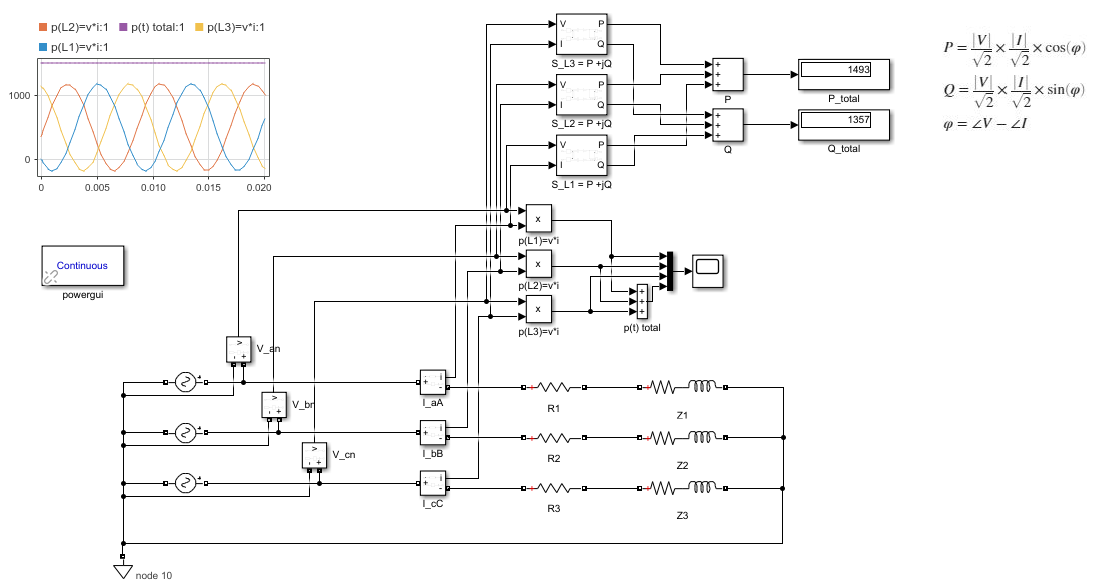

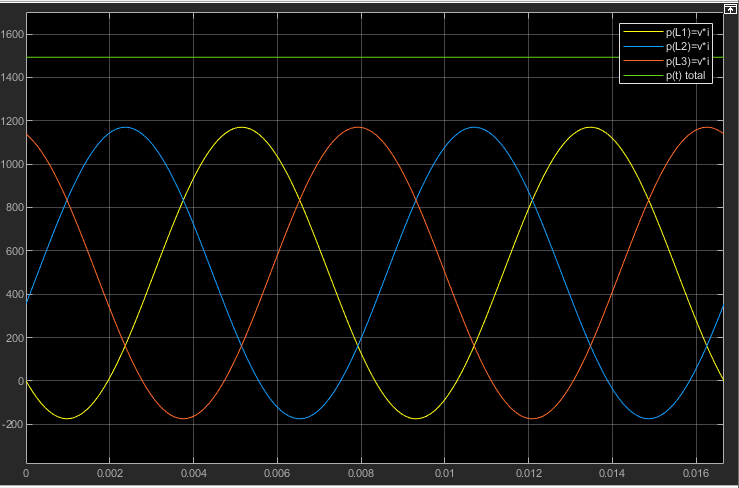

function Complejo = pol2com(M,A)  % magnitud, angulo POLAR A COMPLEJO

    Complejo = M * exp (deg2rad (A) * 1i); 

end

function Polar = com2pol(Z)

    M=abs(Z); %Magnitud
    A=rad2deg(angle(Z));% angulo
    
Polar=[M,A];
end